# Installed Capacity

Description: This algorithm plot the installed capacity by regions. 

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2020

clc
clear
close all

## Load Data

load Data_EIA.mat

## Variables

% Electricity Capacity 

% Electricity installed capacity (million kW)
El_Cap_Tot=Data_EIA.El_Cap_Tot;%[GW]
% nuclear electricity installed capacity (million kW)
El_Cap_Nuc=Data_EIA.El_Cap_Nuc;%[GW]
% fossil fuels electricity installed capacity (million kW)
El_Cap_Fos=Data_EIA.El_Cap_Fos;%[GW]
% renewable electricity installed capacity (million kW)
El_Cap_Ren=Data_EIA.El_Cap_Ren;%[GW]
% hydroelectricity installed capacity (million kW)
El_Cap_Hyd=Data_EIA.El_Cap_Hyd;%[GW]
% geothermal electricity installed capacity (million kW)
El_Cap_Geo=Data_EIA.El_Cap_Geo;%[GW]
% solar electricity installed capacity (million kW)
El_Cap_Sol=Data_EIA.El_Cap_Sol;%[GW]
% wind electricity installed capacity (million kW)
El_Cap_Win=Data_EIA.El_Cap_Win;%[GW]
% biomass and waste electricity installed capacity (million kW)
El_Cap_Bio=Data_EIA.El_Cap_Bio;%[GW]

% Country names
Labels=Data_EIA.Labels;

% Continent code
Continent=Data_EIA.Continent;
% 1	Latin america
% 2	North America
% 3	Africa
% 4	MENA
% 5	CIS
% 6	Europe
% 7	Asia
% 8 Oceania
% 9	Antartica
% 10 World

Year=1980:2017;

Color=[178,24,43        % Africa
       214,96,77        % Asia
       90,174,97        % CIS
       27,120,55        % Europe
       146,197,222      % Latin America
       33,102,172       % MENA
       128,115,172      % North America
       84,39,136        % Oceania
       55,55,55]/255;   % World      

% legend
leg={'$$\mathrm{Africa}$$';'$$\mathrm{Asia}$$';'$$\mathrm{CIS}$$';...
    '$$\mathrm{Europe}$$';'$$\mathrm{Latin~Am.}$$';'$$\mathrm{MENA}$$';...
    '$$\mathrm{North~Am.}$$';'$$\mathrm{Oceania}$$';};

## Get Index Regions

LatAm=find(Continent==1);
NorAm=find(Continent==2);
Africa=find(Continent==3);
MENA=find(Continent==4);
CIS=find(Continent==5);
Europe=find(Continent==6);
Asia=find(Continent==7);
Oceania=find(Continent==8);
Antarctica=find(Continent==9);

## Biomass

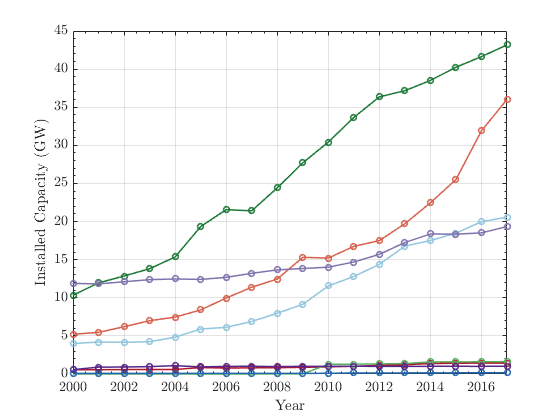

% Installed Capacity
 Africa_Cap_Bio=nansum(El_Cap_Bio(Africa,:));
 Asia_Cap_Bio=nansum(El_Cap_Bio(Asia,:));
 CIS_Cap_Bio=nansum(El_Cap_Bio(CIS,:));
 Europe_Cap_Bio=nansum(El_Cap_Bio(Europe,:));
 LatAm_El_Bio=nansum(El_Cap_Bio(LatAm,:));
 MENA_Cap_Bio=nansum(El_Cap_Bio(MENA,:));
 NorAm_Cap_Bio=nansum(El_Cap_Bio(NorAm,:));
 Oceania_Cap_Bio=nansum(El_Cap_Bio(Oceania,:));
 
figure('Name','Installed Capacity Bio')
plot(Year,Africa_Cap_Bio,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Bio,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Bio,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Bio,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Bio,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Bio,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Bio,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Bio,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Biomass_Capacity.eps');
print('-dpng','-r400','Biomass_Capacity.png');

## Fossil

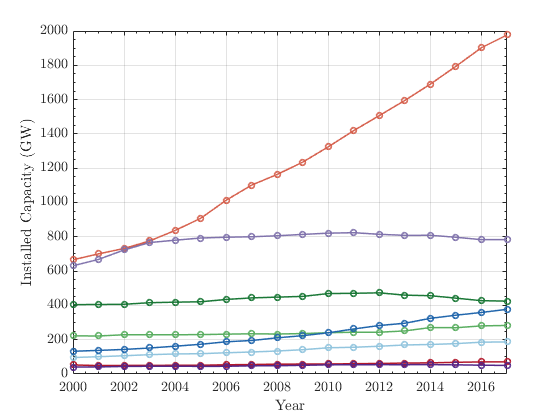

% Installed Capacity
 Africa_Cap_Fos=nansum(El_Cap_Fos(Africa,:));
 Asia_Cap_Fos=nansum(El_Cap_Fos(Asia,:));
 CIS_Cap_Fos=nansum(El_Cap_Fos(CIS,:));
 Europe_Cap_Fos=nansum(El_Cap_Fos(Europe,:));
 LatAm_El_Fos=nansum(El_Cap_Fos(LatAm,:));
 MENA_Cap_Fos=nansum(El_Cap_Fos(MENA,:));
 NorAm_Cap_Fos=nansum(El_Cap_Fos(NorAm,:));
 Oceania_Cap_Fos=nansum(El_Cap_Fos(Oceania,:));
 
figure('Name','Installed Capacity Fos')
plot(Year,Africa_Cap_Fos,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Fos,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Fos,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Fos,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Fos,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Fos,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Fos,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Fos,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Fossil_Capacity.eps');
print('-dpng','-r400','Fossil_Capacity.png');

## Geothermal

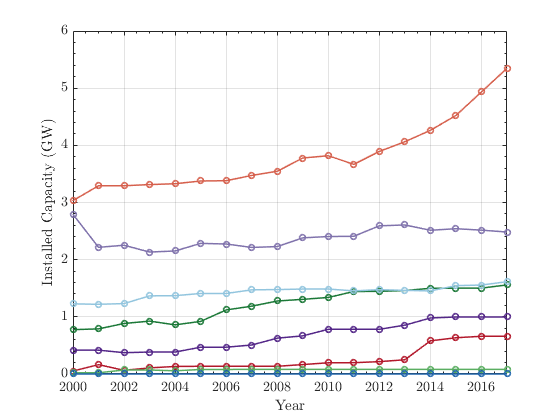

% Installed Capacity
 Africa_Cap_Geo=nansum(El_Cap_Geo(Africa,:));
 Asia_Cap_Geo=nansum(El_Cap_Geo(Asia,:));
 CIS_Cap_Geo=nansum(El_Cap_Geo(CIS,:));
 Europe_Cap_Geo=nansum(El_Cap_Geo(Europe,:));
 LatAm_El_Geo=nansum(El_Cap_Geo(LatAm,:));
 MENA_Cap_Geo=nansum(El_Cap_Geo(MENA,:));
 NorAm_Cap_Geo=nansum(El_Cap_Geo(NorAm,:));
 Oceania_Cap_Geo=nansum(El_Cap_Geo(Oceania,:));
 
figure('Name','Installed Capacity Geo')
plot(Year,Africa_Cap_Geo,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Geo,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Geo,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Geo,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Geo,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Geo,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Geo,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Geo,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Geothermal_Capacity.eps');
print('-dpng','-r400','Geothermal_Capacity.png');

## Hydro

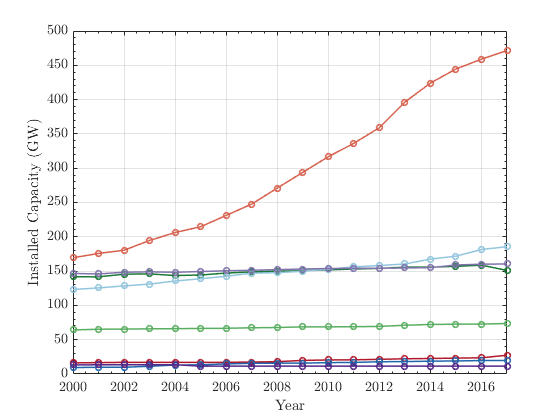

% Installed Capacity
 Africa_Cap_Hyd=nansum(El_Cap_Hyd(Africa,:));
 Asia_Cap_Hyd=nansum(El_Cap_Hyd(Asia,:));
 CIS_Cap_Hyd=nansum(El_Cap_Hyd(CIS,:));
 Europe_Cap_Hyd=nansum(El_Cap_Hyd(Europe,:));
 LatAm_El_Hyd=nansum(El_Cap_Hyd(LatAm,:));
 MENA_Cap_Hyd=nansum(El_Cap_Hyd(MENA,:));
 NorAm_Cap_Hyd=nansum(El_Cap_Hyd(NorAm,:));
 Oceania_Cap_Hyd=nansum(El_Cap_Hyd(Oceania,:));
 
figure('Name','Installed Capacity Hyd')
plot(Year,Africa_Cap_Hyd,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Hyd,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Hyd,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Hyd,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Hyd,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Hyd,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Hyd,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Hyd,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Hydro_Capacity.eps');
print('-dpng','-r400','Hydro_Capacity.png');

## Nuclear

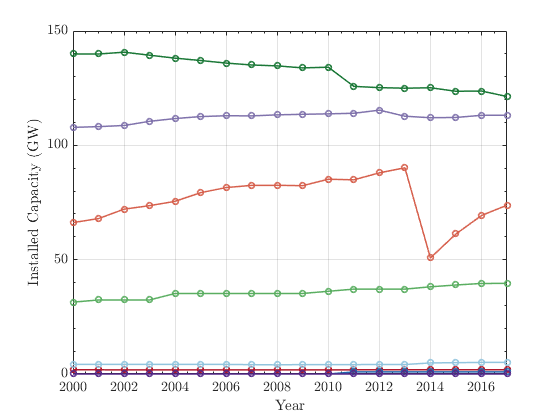

% Installed Capacity
 Africa_Cap_Nuc=nansum(El_Cap_Nuc(Africa,:));
 Asia_Cap_Nuc=nansum(El_Cap_Nuc(Asia,:));
 CIS_Cap_Nuc=nansum(El_Cap_Nuc(CIS,:));
 Europe_Cap_Nuc=nansum(El_Cap_Nuc(Europe,:));
 LatAm_El_Nuc=nansum(El_Cap_Nuc(LatAm,:));
 MENA_Cap_Nuc=nansum(El_Cap_Nuc(MENA,:));
 NorAm_Cap_Nuc=nansum(El_Cap_Nuc(NorAm,:));
 Oceania_Cap_Nuc=nansum(El_Cap_Nuc(Oceania,:));
 
figure('Name','Installed Capacity Nuc')
plot(Year,Africa_Cap_Nuc,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Nuc,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Nuc,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Nuc,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Nuc,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Nuc,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Nuc,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Nuc,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Nuclear_Capacity.eps');
print('-dpng','-r400','Nuclear_Capacity.png');

## Solar

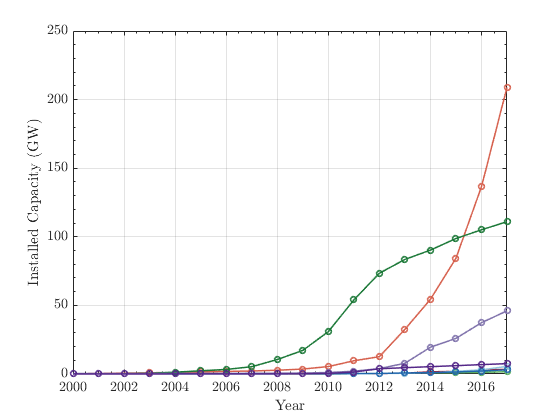

% Installed Capacity
 Africa_Cap_Sol=nansum(El_Cap_Sol(Africa,:));
 Asia_Cap_Sol=nansum(El_Cap_Sol(Asia,:));
 CIS_Cap_Sol=nansum(El_Cap_Sol(CIS,:));
 Europe_Cap_Sol=nansum(El_Cap_Sol(Europe,:));
 LatAm_El_Sol=nansum(El_Cap_Sol(LatAm,:));
 MENA_Cap_Sol=nansum(El_Cap_Sol(MENA,:));
 NorAm_Cap_Sol=nansum(El_Cap_Sol(NorAm,:));
 Oceania_Cap_Sol=nansum(El_Cap_Sol(Oceania,:));
 
figure('Name','Installed Capacity Sol')
plot(Year,Africa_Cap_Sol,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Sol,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Sol,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Sol,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Sol,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Sol,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Sol,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Sol,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Solar_Capacity.eps');
print('-dpng','-r400','Solar_Capacity.png');

## Wind

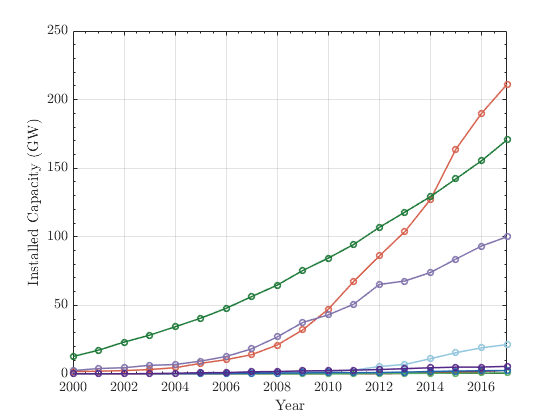

% Installed Capacity
 Africa_Cap_Win=nansum(El_Cap_Win(Africa,:));
 Asia_Cap_Win=nansum(El_Cap_Win(Asia,:));
 CIS_Cap_Win=nansum(El_Cap_Win(CIS,:));
 Europe_Cap_Win=nansum(El_Cap_Win(Europe,:));
 LatAm_El_Win=nansum(El_Cap_Win(LatAm,:));
 MENA_Cap_Win=nansum(El_Cap_Win(MENA,:));
 NorAm_Cap_Win=nansum(El_Cap_Win(NorAm,:));
 Oceania_Cap_Win=nansum(El_Cap_Win(Oceania,:));
 
figure('Name','Installed Capacity Win')
plot(Year,Africa_Cap_Win,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_Cap_Win,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_Cap_Win,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_Cap_Win,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Win,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_Cap_Win,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_Cap_Win,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_Cap_Win,'-o','Color',Color(8,:),'linewidth',1.5)
xlim([2000 2017])
% legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
%     'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Installed~Capacity~(GW)}$$','interpreter','latex')

box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Wind_Capacity.eps');
print('-dpng','-r400','Wind_Capacity.png');